# Assignment 1.1: Teaching a Cylrindrical Mechanical Manipualtor (RRP)

Objective:

 - to create and to simulate a Cylindrical Mechanical Manipulator using the Robotics Toolbox for MATLAB by Peter Corke

disp("Spherical Manipulator (RRP)")

Spherical Manipulator (RRP)


syms a1 a2 a3 a4

## Step 1: Define the Link Lengths

a1 = 5;
a2 = 5;
a3 = 1;

## Step 2: Using the Prismatic and Revolute class to create the HTM

H_01 = Revolute('alpha', 3*pi/2, 'd', a1)

 
H_01 = 
Revolute(std): theta=q, d=5, a=0, alpha=1.5708, offset=0


H_12 = Revolute('alpha', pi/2, 'a', a2, 'offset', pi/2)

 
H_12 = 
Revolute(std): theta=q, d=0, a=0, alpha=1.5708, offset=1.5708


H_23 = Prismatic('offset', a2)

 
H_23 = 
Prismatic(std): theta=0, d=q, a=0, alpha=0, offset=6



% define the following limits

H_01.qlim = [-pi/2, pi/2];
H_12.qlim = [-pi/2, pi/2];
H_23.qlim = [0, 10];

## Step 3: Create the Manipulator via Serial Link Class

spherical_manip = SerialLink([H_01, H_12, H_23], 'name', 'Spherical Modern Variant')

 
spherical_manip = 
 
Spherical Modern Variant:: 3 axis, RRP, stdDH, slowRNE           
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          5|          0|     1.5708|          0|
|  2|         q2|          0|          0|     1.5708|     1.5708|
|  3|          0|         q3|          0|          0|          6|
+---+-----------+-----------+-----------+-----------+-----------+
 


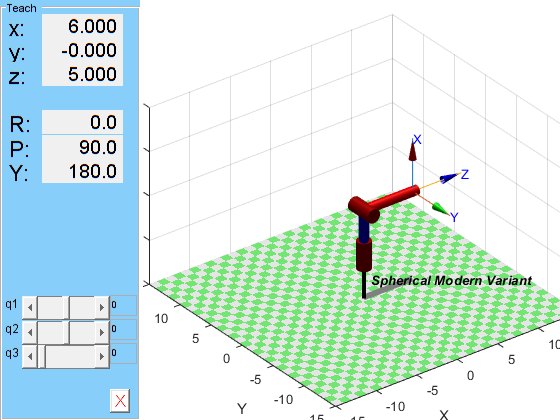


joint_setpoint = [0,0,0];
workspace = [-15, 15, -15, 15, -5, 15];
spherical_manip.plot(joint_setpoint, 'workspace', workspace);
spherical_manip.teach();